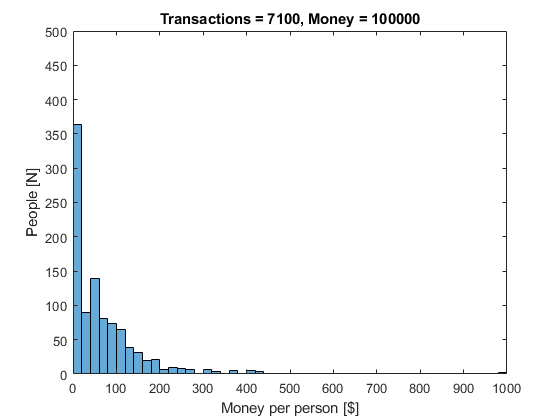

Error using histogram
Expected input number 2, edges, to be a vector.

Error in histogram>parseinput (line 293)
                    validateattributes(in,{'numeric','logical'},{'vector','nonempty', ...

Error in histogram (line 145)
[opts,passthrough,dispatchToCategorical] = parseinp

clc; clear; close all; format short;

% RESTRICTIONS
N = 1e3;            % Quantity of agents
n = 1e4;            % Quantity of iterarions
M = 1e5;            % Quantity of money       
V = 0;              % Market Value initiation
yr = 1;             % Initiate year
k = 0:20:1000;      % Bins for histograms

% VECTORS' INITIATION
m = M/N*ones(N,1);                  % Money's vector initiation (equally distributed)
condition = zeros(N,1);             % Condition vector initiation (everyone is unemployed)
H = zeros(N,3);                     % Hiring vector initiation
S = nan(n,1);                       % Entropy vector initiation
Well = nan(n,1);                    % Well vector initiation
Capitalist = zeros(1,n);            % Capitalists vector initiation
Unemployed = zeros(1,n);            % Unemployeds vector initiation 
Employed = zeros(1,n);              % Employeds vector initiation 
A = [(1:N)' m condition];           % Agents' vector
wa = 40; wb = 60; w = ceil((wa+wb)/2);  % Average salary
incomeWorkr = zeros(N,n/N);         % Yearly income vector

for t = 1:n
    yr = countYear(yr,t,N);         % Year's counter                        
    a = randi(N);                   % Random actor a
    if isUnemployed(A,a)            % Unemployment condition
        unemployed = A(:,3) == 0;   % unemployed agents
        H = [A(unemployed,1) A(unemployed,2) A(unemployed,2)/sum(A(unemployed,2))];
        weight = H(:,3);
        idx = H(:,1);
        c = randsample(idx,1,true,weight);
        if (c==a); c = 0;
        elseif (A(c,2)<w); c = 0;
        end
        A(a,3) = c;             % Cambiamos al indice del jefe
    end
    
    % EXPENDITURE ON GOODS 
    b = randi(N);                   % Random actor b
    mb = A(b,2);                    % Money of b
    if (mb > 0); buy = randi(mb);   % Random buy from 0 to b's money  
    else; buy = 0;
    end
    mb = mb - buy; A(b,2) = mb;
    V = V + buy;
    
    % FIRMS AND MARKET VALUE 
    if (V > 0)
        sell = randi(V);
        if isEmployed(A,a)
            bossID = A(a,3);
            A(bossID,2) = A(bossID,2) + sell;
            V = V - sell;
        end
        if isCapitalist(A,a) 
            A(a,2) = A(a,2) + sell;
            V = V - sell;
        end
    end
    
    % EMPLOYEE FIRING
    bossIDs = A(:,3);
    workrsID = bossIDs == a;
    workrs = A(workrsID,1);
    nWorkrs = sum(workrsID);
        
    if isCapitalist(A,a) && w*nWorkrs > A(a,2)
        fire = ceil(abs(nWorkrs-(A(a,2)/w*nWorkrs)));
        if fire > nWorkrs
          A(workrsID,3) = 0;
        else
          fired = workrs(randperm(nWorkrs,fire));
          A(fired,3) = 0;
        end
    end
    
    % WAGE PAYMENT
    wage = randi([wa wb],1);
    pay = wage*length(workrs);
    ma = A(a,2);
    if ma >= pay
        ma = ma - pay;
        A(workrs,2) = A(workrs,2) + wage;
        incomeWorkr(a,yr) = incomeWorkr(a,yr) + wage;
    else
        for j = 1:length(workrs)
            if ma >= wage
                ma = ma - wage;
                A(workrs(j),2) = A(workrs(j),2) + wage; 
                incomeWorkr(a,yr) = incomeWorkr(a,yr) + wage;
            else
                wage = randi([0 ma],1);
                ma = ma - wage;
                A(workrs(j),2) = A(workrs(j),2) + wage;
                incomeWorkr(a,yr) = incomeWorkr(a,yr) + wage;
            end
        end
    end; A(a,2) = ma;
    clear H; clear workrs
    M = sum(A(:,2)) + V;

    moneyHist(A,t,M,N,k);
    h = histcounts(A(:,2),k);
    Well(t) = measureWell(h,k);
    S(t) = measureEntropy(h,N);
    Capitalist(t) = sum(isCapitalist(A,A(:,1)));
    Unemployed(t) = sum(isUnemployed(A,A(:,1)));
    Employed(t) = sum(isEmployed(A,A(:,1)));
end

subplot(1,3,1); classHist(Capitalist,"Capitalists",k)
subplot(1,3,2); classHist(Unemployed,'Unemployees',k)
subplot(1,3,3); classHist(Employed,'Employees',k)
figure
subplot(2,1,1); plot(Well,'-'); title('Bienestar o_k = 1-e^{-aM_k}'); xlabel('t'); ylabel('O')
subplot(2,1,2); plot(S,'-'); title('Entrophy'); xlabel('t'); ylabel('S')
figure
histogram(incomeWorkr(:,yr),k); title('Employees income distribution'); xlabel('Money [$]'); ylabel('Frequency')

function yr = countYear(yr,t,N)
    if mod(10*N,t) == 0
        yr = yr + 1;
    end
    if yr == 11; yr = yr-1; end
end
function out = isUnemployed(agents,id)
    out = zeros(1,length(id));
    for i = 1:length(id)
        out(i) = (agents(id(i),3) == 0) & ~(any(agents(:,3)==id(i)));
    end
end
function out = isEmployed(agents,id)
    out = agents(id,3) ~= 0;
end
function out = isCapitalist(agents,id)
    out = zeros(1,length(id));
    for i = 1:length(id)
        out(i) = (agents(id(i),3) == 0) & any(agents(:,3)==id(i));
    end
end
function moneyHist(agents,time,money,N,k)
    if mod(time,100) == 0 || time == 1
        clf
        histogram(agents(:,2),k);
        title("Transactions = "+num2str(time)+", Money = "+num2str(money))
        ylabel('People [N]'); xlabel('Money per person [$]'); axis([0 1000 0 N/2]); 
        drawnow
    end    
end
function classHist(class,tit,k)
%     global k
    histogram(class,k); xlim([min(k) max(k)]); 
    title(tit); xlabel('People'); ylabel('Frequency')
end
function Well = measureWell(h,k)
    a = 1;
    Mclass = h.*k(2:end);
    oclass = 1-exp(-a*Mclass);
    Well = sum(oclass,'omitnan');
end
function S = measureEntropy(h,N)
    sk = h.*log(h);
    S = N*log(N)-sum(sk,"omitnan");
end